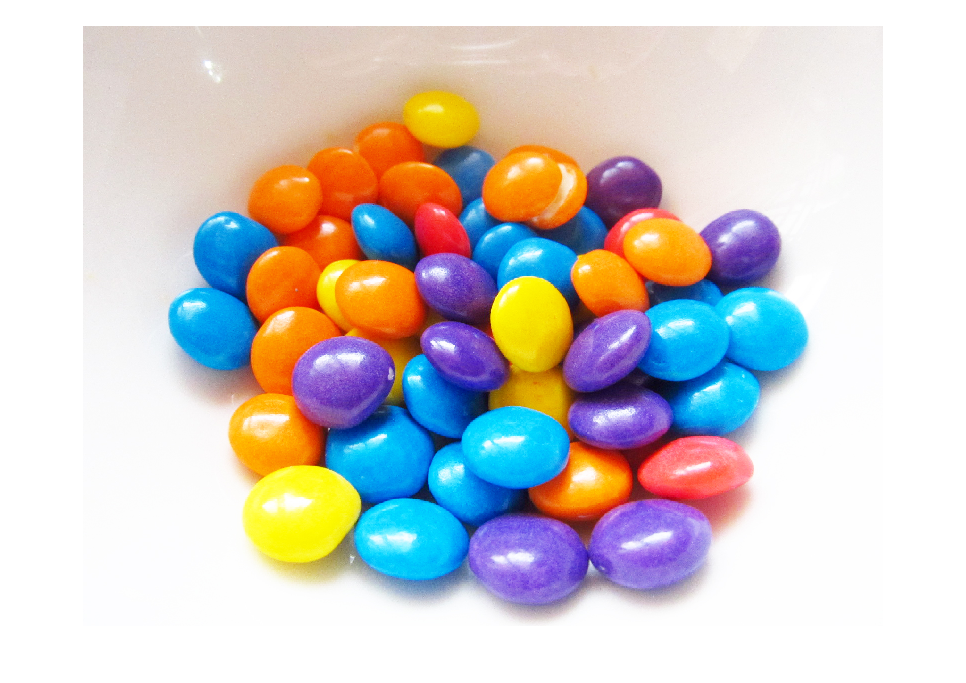

BINS = 32;
[filename, pathname] = uigetfile('nips.jpg');
J = imread([pathname, filename]);

[I, rect] = imcrop(J); 

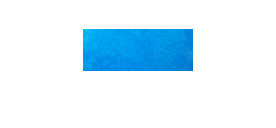

figure; imshow(I);

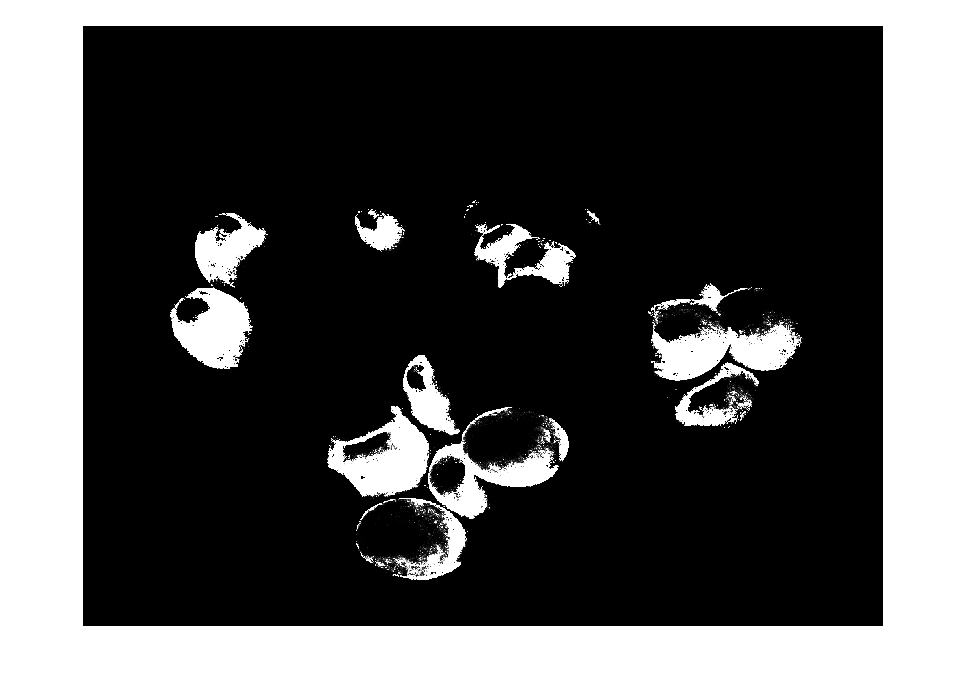


%Parametric Probability Distribution Estimation
% Get the r g of the whole image
J = double(J);
R = J(:,:,1);
G = J(:,:,2);
B = J(:,:,3);


Int = R + G + B;
Int(Int==0) = 1000000; % to prevent NaNs
rJ = R ./ Int;
gJ = G ./ Int;

I = double(I);
RI = I(:,:,1);
GI = I(:,:,2);
BI = I(:,:,3);
IntI = RI + GI + BI;
IntI(IntI==0) = 1000000; % to prevent NaNs
rI = RI ./ IntI;
gI = GI ./ IntI;

mean_r = mean(rI(:));
sigma_r = std(rI(:));
mean_g = mean(gI(:));
sigma_g = std(gI(:));

pr = (1./(sigma_r * sqrt(2*pi))) .* exp(-((rJ - mean_r).^2) ./ (2 * sigma_r.^2));
pg = (1./(sigma_g * sqrt(2*pi))) .* exp(-((gJ - mean_g).^2) ./ (2 * sigma_g.^2));
final = pr .* pg;
figure; imshow(final); 
colormap (gray);

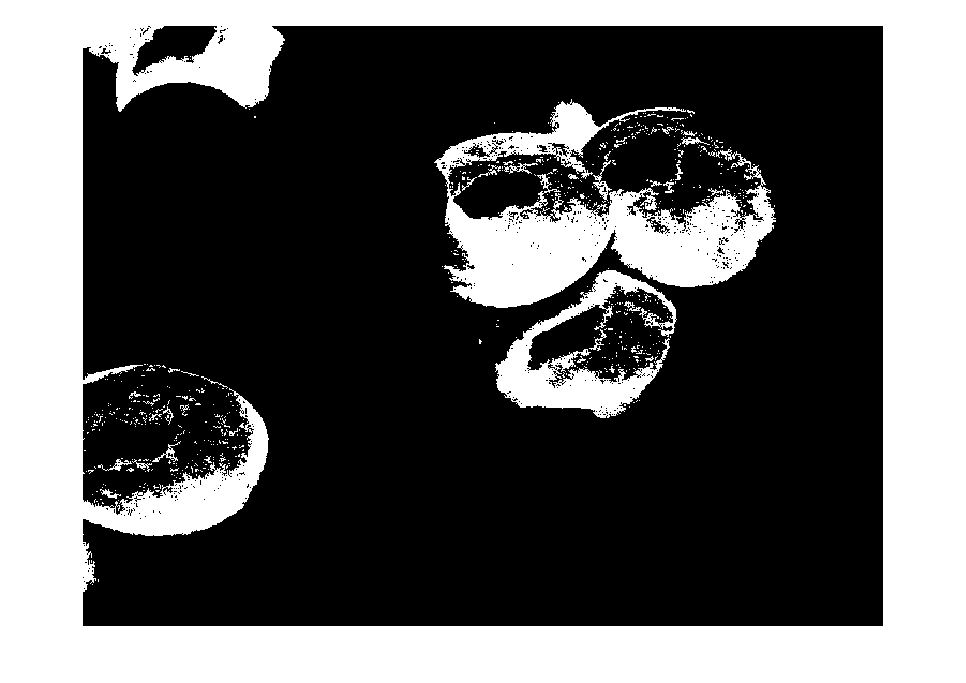


%Non-parametric Probability Distribution Estimation
%% Crop the region of interest in the rg space
     
    r = imcrop(rJ, rect);
    g = imcrop(gJ, rect);
    rint = round( r*(BINS-1) + 1);
    gint = round (g*(BINS-1) + 1);
    colors = gint(:) + (rint(:)-1)*BINS;
    
%% Compute rg-histogram
% This is the 1-d version of a 2-d histogram
    hist = zeros(BINS*BINS,1);
    for row = 1:BINS
    for col = 1:(BINS-row+1)
    hist(col+(row-1)*BINS) = length( find(colors==( ((col + (row-1)*BINS)))));
    end
    end

%% Backproject histogram
    rJint = round( rJ*(BINS-1) + 1);
    gJint = round (gJ*(BINS-1) + 1);
    colorsJ = gJint(:) + (rJint(:)-1)*BINS;
    HB = hist(colorsJ);
    HBImage = reshape(HB,size(J,[1,2]));
    figure (2); imshow(HBImage); 
    colormap (gray);

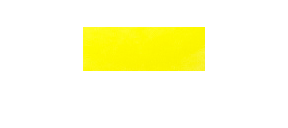

BINS = 32;
[filename, pathname] = uigetfile('nips.jpg');
J = imread([pathname, filename]);

[I, rect] = imcrop(J);
figure; imshow(I);

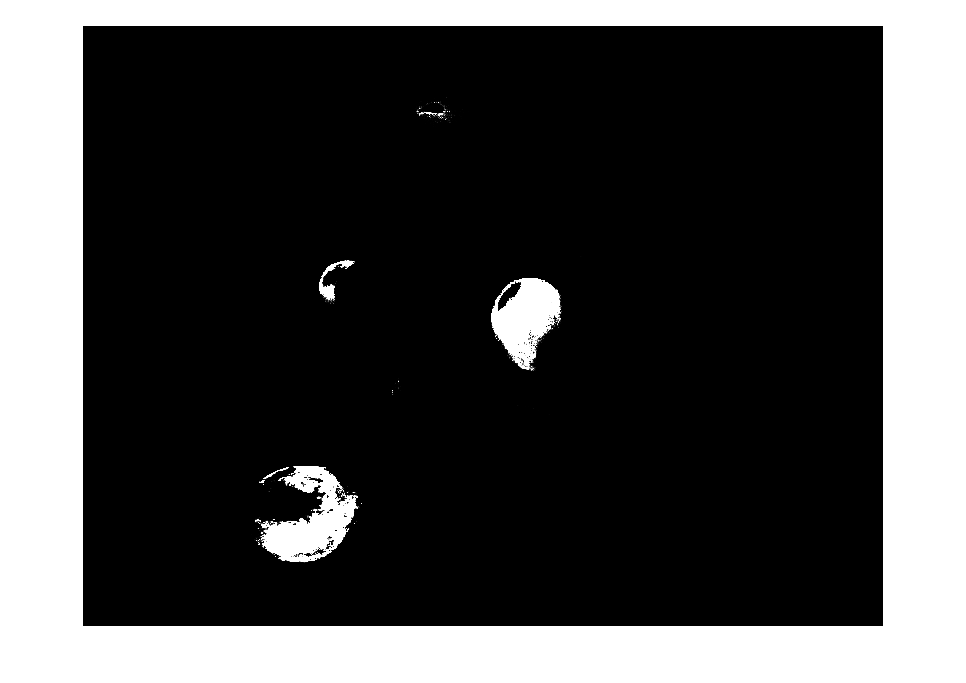


%Parametric Probability Distribution Estimation
% Get the r g of the whole image
J = double(J);
R = J(:,:,1);
G = J(:,:,2);
B = J(:,:,3);


Int = R + G + B;
Int(Int==0) = 1000000; % to prevent NaNs
rJ = R ./ Int;
gJ = G ./ Int;

I = double(I);
RI = I(:,:,1);
GI = I(:,:,2);
BI = I(:,:,3);
IntI = RI + GI + BI;
IntI(IntI==0) = 1000000; % to prevent NaNs
rI = RI ./ IntI;
gI = GI ./ IntI;

mean_r = mean(rI(:));
sigma_r = std(rI(:));
mean_g = mean(gI(:));
sigma_g = std(gI(:));

pr = (1./(sigma_r * sqrt(2*pi))) .* exp(-((rJ - mean_r).^2) ./ (2 * sigma_r.^2));
pg = (1./(sigma_g * sqrt(2*pi))) .* exp(-((gJ - mean_g).^2) ./ (2 * sigma_g.^2));
final = pr .* pg;
figure; imshow(final); 
colormap (gray);

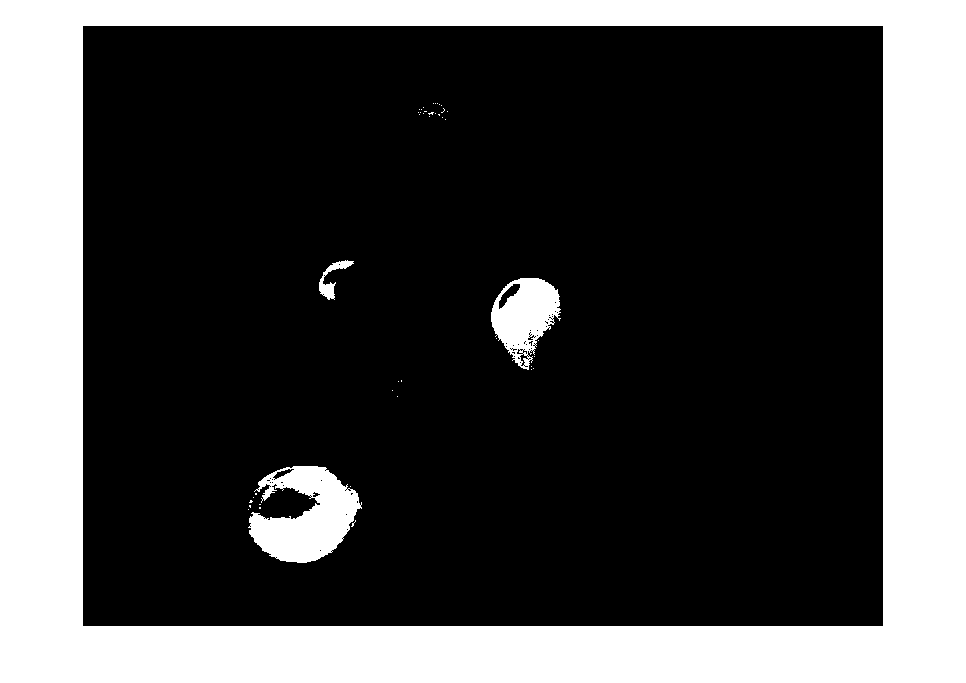



%Non-parametric Probability Distribution Estimation
%% Crop the region of interest in the rg space
     
    r = imcrop(rJ, rect);
    g = imcrop(gJ, rect);
    rint = round( r*(BINS-1) + 1);
    gint = round (g*(BINS-1) + 1);
    colors = gint(:) + (rint(:)-1)*BINS;
    
%% Compute rg-histogram
% This is the 1-d version of a 2-d histogram
    hist = zeros(BINS*BINS,1);
    for row = 1:BINS
    for col = 1:(BINS-row+1)
    hist(col+(row-1)*BINS) = length( find(colors==( ((col + (row-1)*BINS)))));
    end
    end

%% Backproject histogram
    rJint = round( rJ*(BINS-1) + 1);
    gJint = round (gJ*(BINS-1) + 1);
    colorsJ = gJint(:) + (rJint(:)-1)*BINS;
    HB = hist(colorsJ);
    HBImage = reshape(HB,size(J,[1,2]));
    figure (2); imshow(HBImage); 
    colormap (gray);